# Population growth model

This script contains code that models the growth of a poulation in two ways: **exponential** and **logistic**. Use the interactive controls below to change the model parameters and see their effect on the population growth. The simulation will run each time you change a parameter value.

## Select model parameters

mtype = "logistic";       % Type of model to run: exponential or logistic
N0    = 1;       % Initial population size
r     =0.1; % Population growth rate
K     = 100 ;      % Carrying capacity [only matters for logistic]
t     = 200;       % Number of generations
tau   =0;   % Population response time lag [only matters for logistic]

Time lags (a delay in when the population size affects the growth rate) are really interesting. Try playing with increasingly large time lags and watch what happens

## Run model

%Make the "storage variables"
generation = linspace(0,t,t+1);
dNdt = zeros(size(generation));
population = zeros(size(generation));

%"If" statement selects appropriate model
if mtype == "exponential"   %run the exponential growth model
    for i = 1:size(generation,2)    
        if i == 1   %The generation has population = N0
            population(i) = N0;
            dNdt(i) = r*population(i);
        else
            population(i) = population(i-1)+dNdt(i-1); %At the new
            %timestep, the population has grown by dNdt from the previous
            %generation
            dNdt(i) = r*population(i);
        end
    end
    
elseif mtype == "logistic"   %run the logistic growth model
    for i = 1:size(generation,2)
        if i == 1
            population(i) = N0;
            dNdt(i) = r*population(i)*(1-population(i)/K);
        else
            if i <= tau  %If you have a time lag (tau > 0) you need this 
                %alternate logistic equation without time lag to get you through
                %the first few generations.
                population(i) = population(i-1)+dNdt(i-1);
                dNdt(i) = r*population(i)*(1-population(i)/K);
            else
                population(i) = population(i-1)+dNdt(i-1);
                dNdt(i) = r*population(i)*(1-population(i-tau)/K);
            end
        end
    end
end

## Visualize results

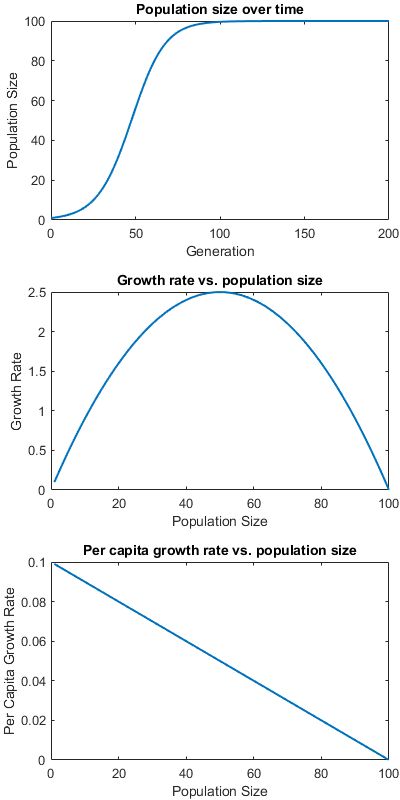

%Make a plot to look at your results
figure('Position',[50 50 400 800]);
tiledlayout(3,1,'Padding','tight')

nexttile
plot(generation,population,'LineWidth',1.5)
xlabel('Generation')
ylabel('Population Size')
title('Population size over time')

nexttile
plot(population,dNdt,'LineWidth',1.5) 
xlabel('Population Size')
ylabel('Growth Rate')
title('Growth rate vs. population size')

nexttile
plot(population,dNdt./population,'LineWidth',1.5)
xlabel('Population Size')
ylabel('Per Capita Growth Rate')
title('Per capita growth rate vs. population size')

Note that with the logistic model and a time lag you get multiple growth rate values for the same population size (which makes sense, because the population's growth rate depends both on its current size, and on its size at some past time point). This results in some pretty spirals.

The middle panel is basically the derivative of the upper panel. It is useful if you want to show that the growth rate of a population depends upon its size. And, if you have a logistic model with no time lags, it gives a nice demonstration of why MSY (maximum sustainable yield, a fisheries concept) is at `K/2`.

The bottom panel plot allows us to see that the density dependence of the growth rate varies with growth model. In exponential growth, per capita reproduction (`dNdt/N)` is a constant (`r`). In logistic growth, per capita reproductive rate decreases with increasing population density.